# Process the intensity data from Idler

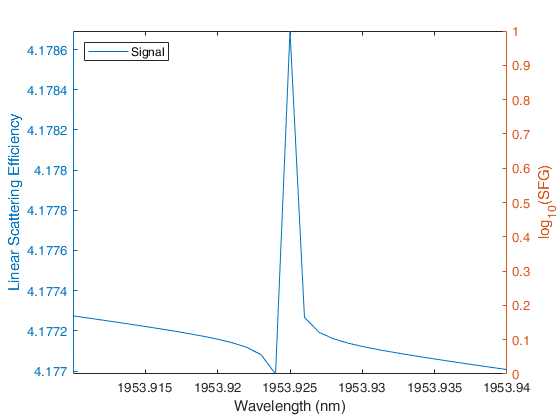

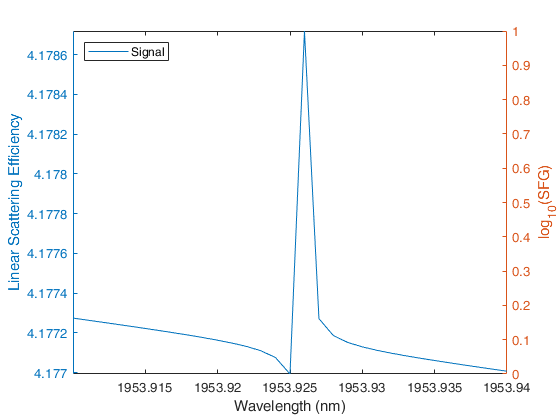

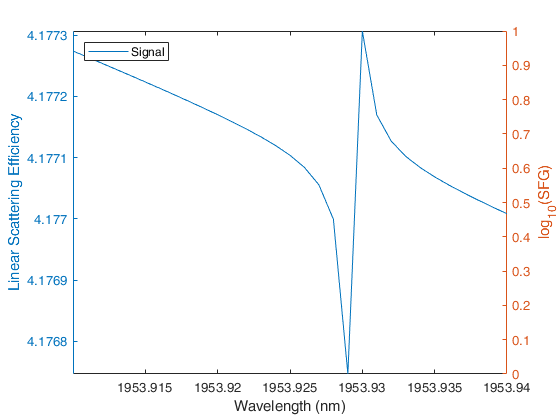

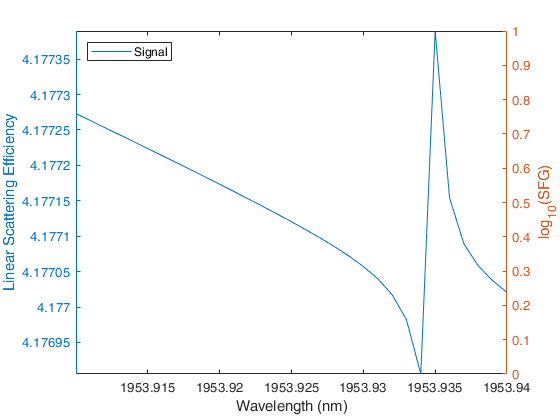

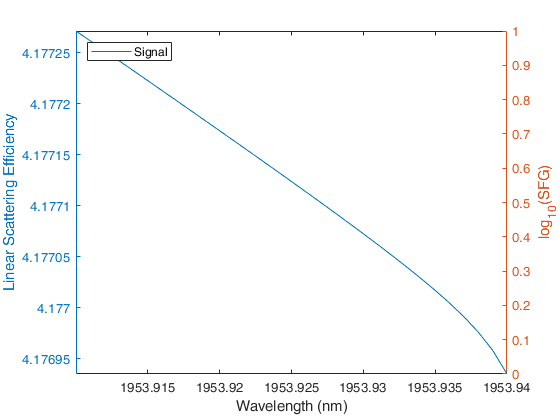

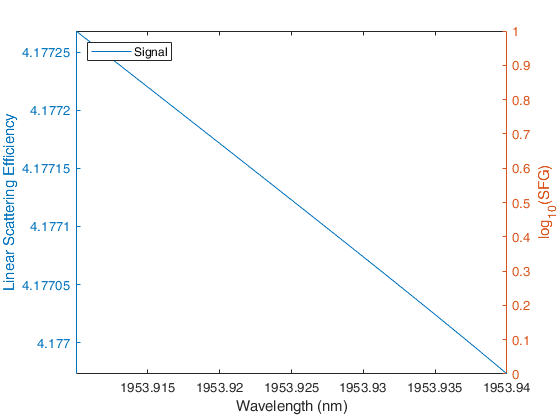

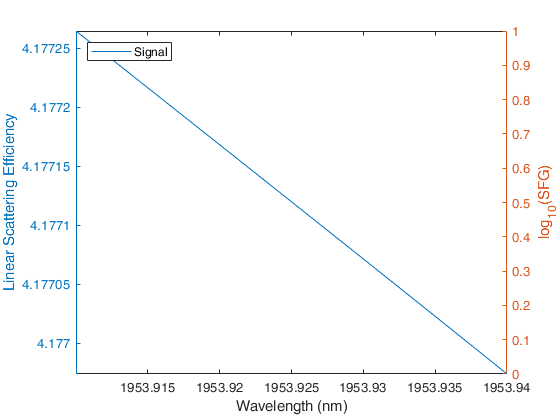

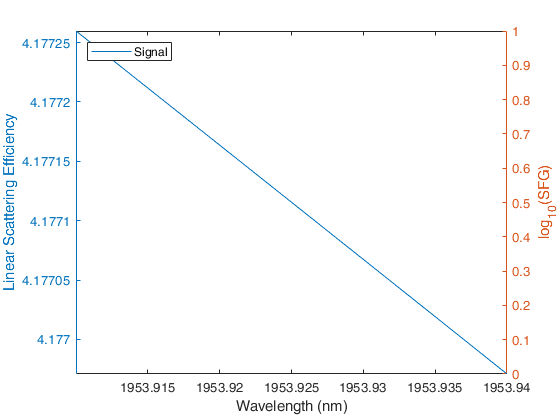

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis');
eval("cylinder_dimer_no_substrate_110_2_4");
load([options.output_dir_final 'sweep_data.mat']);

for theta = get_range("step", 0,0.1,1,"[deg]")
%    for phi = ["0[deg]" "90[deg]"]
%        for orientation_xy = "0[deg]"% "45[deg]" "90[deg]"]
%            data = sweep_data(sweep_data.theta == theta & sweep_data.phi == phi...
%                & sweep_data.orientation_xy == orientation_xy,:);
            data = sweep_data(sweep_data.theta == theta,:);
            
            derived_values = data.DerivedValues{1};
            sum_fft = data.SumFFT{1};
            
            wlengths = 299792458./derived_values.signal.freq;
            
            figure;
            yyaxis left;
            plot(wlengths,derived_values.signal.scat_eff); % scat3_eff
            hold on
            ylabel('Linear Scattering Efficiency');
            yyaxis right;
            %plot(wlengths,log10(derived_values.sfg.scat3_eff)); % int_Isfg
            leg = legend({'Signal','log_{10}(SFG)'});
            leg.Location = 'northwest';
            xlabel('Wavelength (nm)');
            ylabel('log_{10}(SFG)');
            %title(strcat('\theta=', theta, ', \phi=', phi, ', \alpha=', orientation_xy));
            axis tight;
%        end
%    end
end